Scenario 2: Different dimensions of the two obstacles which creates a local minima causing the motion plan to fail.

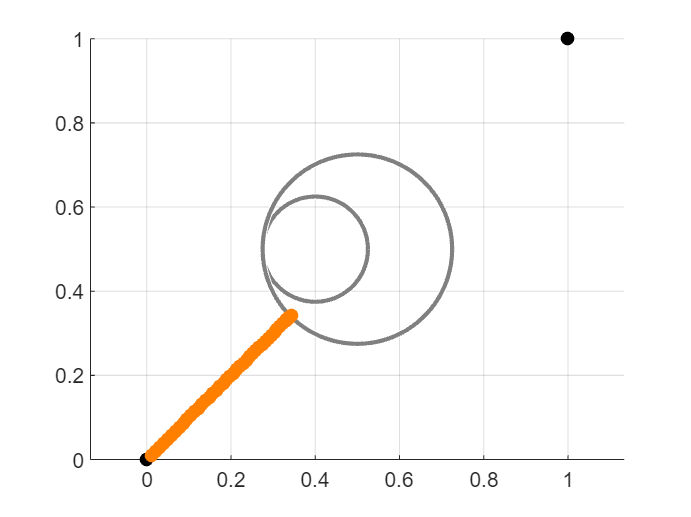

clear
close all

% Parameters
theta_start = [0; 0];
theta_goal = [1; 1];
centers = [.4, .5; .5, .5];
radii = [.125, .225];

% Create figure
figure
grid on
hold on
for idx = 1:length(radii)
 viscircles(centers(:,idx)', radii(idx), 'Color', [0.5, 0.5, 0.5]);
end

plot(theta_start(1), theta_start(2), 'ko', 'MarkerFaceColor', 'k')
plot(theta_goal(1), theta_goal(2), 'ko', 'MarkerFaceColor', 'k')
axis equal

% Gradient descent down potential field
theta = theta_start;
delta = 0.01;
learning_rate = 0.01;

for idx = 1:1000
 if norm(theta - theta_goal) < 0.1
 break
 end

 U = field(theta, theta_goal, centers, radii);
 U1 = field(theta + [delta; 0], theta_goal, centers, radii);
 U2 = field(theta + [0; delta], theta_goal, centers, radii);
 Ugrad = [U1 - U; U2 - U] / delta;
 theta = theta - learning_rate * Ugrad;
 plot(theta(1), theta(2), 'o', 'color', [1, 0.5, 0], ...
 'MarkerFaceColor', [1, 0.5, 0])
end


% Find potential field at position theta

function U = field(theta, theta_goal, centers, radii)
 U = 0.5 * norm(theta_goal - theta)^2;
 for idx = 1:length(radii)
 center = centers(:, idx);
 radius = radii(idx);
 dist = norm(center - theta);
 if dist < radius
 U = U + 0.5 * (1/dist - 1/radius)^2;
 end
 end
end

In this modification, the obstacles are placed closer to each other, potentially creating a narrow corridor that the drone might not be able to navigate due to the combined repulsive forces. This setup can result in the planner getting stuck in a** local minimum**, where the drone is unable to progress towards the goal. Thus, we place a local minimim in between the start and goal.  Gradient descent can only climb "down" so if **it's surrounded by high gradients**, it can't escape.